# Test Trained Landcover Network

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the landcover dataset.

load ../data/satData.mat
categories(YTrain)

ans = 6×1 cell array
    {'barren land'}
    {'building'   }
    {'grassland'  }
    {'road'       }
    {'trees'      }
    {'water'      }


This code loads a network trained with the following command:

layers = [  imageInputLayer([28 28 4])
            convolution2dLayer(3, 20)
            reluLayer()
            maxPooling2dLayer(3)
            fullyConnectedLayer(6)
            softmaxLayer()
            classificationLayer()]

layers =   7×1 Layer array with layers:

     1   ''   Image Input             28×28×4 images with 'zerocenter' normalization
     2   ''   2-D Convolution         20 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   2-D Max Pooling         3×3 max pooling with stride [1  1] and padding [0  0  0  0]
     5   ''   Fully Connected         6 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       18.75% |     101.9541 |      1.0000e-04 |
|       2 |          46 |       00:00:06 |       91.41% |       4.8236 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


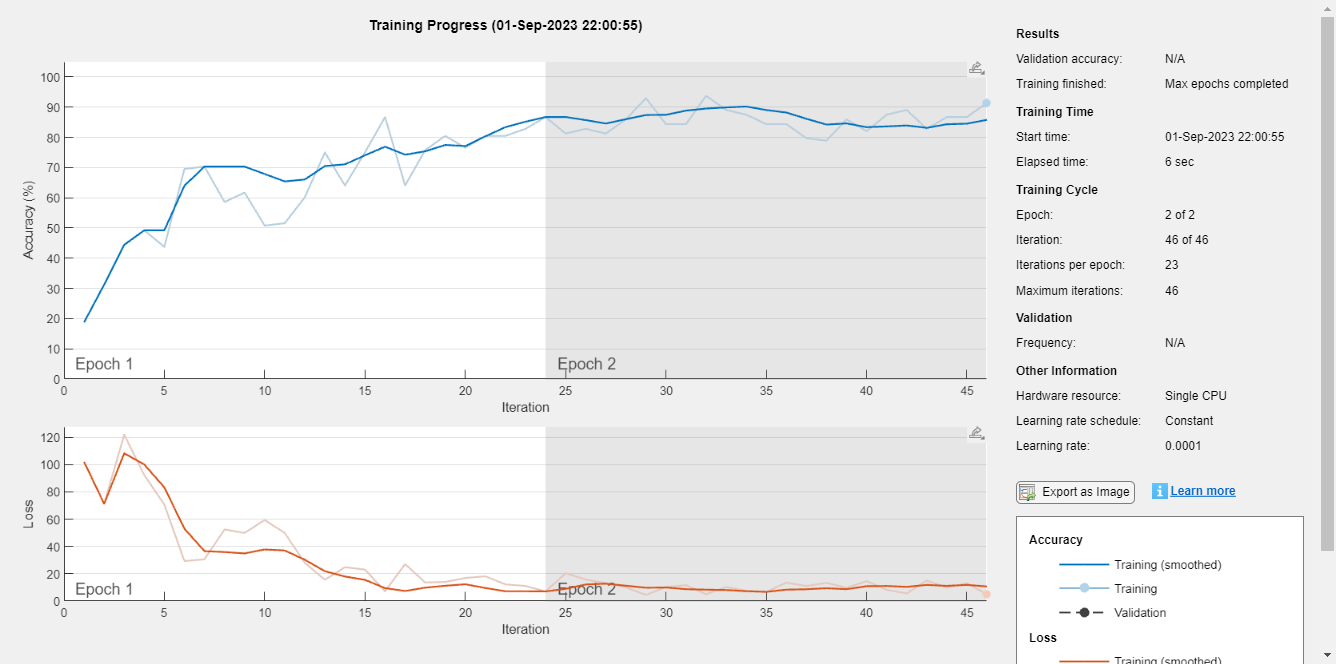


options = trainingOptions("sgdm", "MaxEpochs", 2, "InitialLearnRate", 0.0001, "Plots", "training-progress");
landnet = trainNetwork(XTrain, YTrain, layers, options);

## Task 1

Training the network takes some time, so a network named `landnet` has been trained using the data, architecture, and options that you specified. It has been loaded into the workspace. You'll have a chance to train this network in the next module.

The test data is stored in a variable `XTest`, and the corresponding labels are in `YTest`.

You can use the `classify` function to make predictions with your network. The first input to `classify` is the network and the second input is the data to classify.

testpreds = classify(landnet, XTest);

## Task 2

Recall that you can view a confusion matrix using the `confusionchart` function.

`confusionchart``(``known``,``predicted``)`

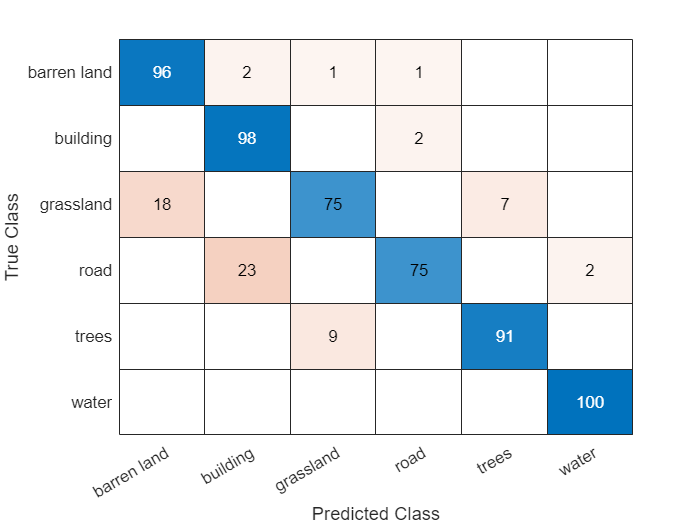

confusionchart(YTest, testpreds)